Tutorial03 Assignment

2.4 Plotting Trajectories

**2.3 Wandering on a Plane - Generating Trajectories**

Now: Want to create a rand walk of 500 steps.

=> Our trajectory will be a list of 500 x values and 500 y values.

Note: It's a good practice to let MATLAB know the length of the lists, bc it saves computation time.

walklength = 500;
x = zeros(1, walklength); y = zeros(1, walklength)

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


eqn1 shows that we can consider x and y separately.

% Creating two lists of 500 random binary digits
rlistx = rand(1, walklength);
rlisty = rand(1, walklength);
stepx = (rlistx>0.5);
stepy = (rlisty>0.5);
sum(stepx);
sum(stepx);

rlistx2 = rand(1, walklength);
rlisty2 = rand(1, walklength);
stepx2 = (rlistx2>0.5);
stepy2 = (rlisty2>0.5);
sum(stepx2);
sum(stepx2);

rlistx3 = rand(1, walklength);
rlisty3 = rand(1, walklength);
stepx3 = (rlistx3>0.5);
stepy3 = (rlisty3>0.5);
sum(stepx3);
sum(stepx3);

Now, convert the lists of steps into actual successive positions of the random walker.

a)  b)

Make three random walk trajectories.

% help cumsum
stepx = cumsum(-1+2*stepx)

stepx =      1     0     1     2     3     4     3     2     1     0    -1     0     1     0     1     2     1     2     3     2     3     2     3     4     3     2     3     2     1     2     3     2     1     0    -1    -2    -1    -2    -1     0     1     0    -1     0     1     0     1     0     1     2


stepy = cumsum(-1+2*stepy)

stepy =     -1     0    -1     0     1     2     3     4     5     4     5     6     5     6     7     6     7     6     7     8     7     6     7     8     7     8     7     8     7     8     9    10    11    10     9    10     9    10     9    10    11    10    11    10     9    10    11    12    13    12



stepx2 = cumsum(-1+2*stepx2)

stepx2 =      1     0    -1     0     1     2     1     0     1     0    -1     0    -1     0     1     2     3     4     5     6     7     6     7     8     9    10     9     8     9    10    11    10     9     8     7     8     9     8     7     8     7     6     7     8     9     8     9    10    11    12


stepy2 = cumsum(-1+2*stepy2)

stepy2 =     -1    -2    -3    -4    -5    -6    -5    -4    -5    -4    -5    -6    -7    -6    -5    -6    -5    -6    -5    -4    -3    -2    -1    -2    -1     0     1     0    -1    -2    -1     0    -1    -2    -3    -2    -1     0     1     2     3     2     3     4     3     2     3     4     5     4



stepx3 = cumsum(-1+2*stepx3)

stepx3 =      1     2     1     0     1     0    -1     0    -1     0     1     2     1     2     3     4     5     6     7     6     7     6     5     4     3     2     3     4     3     2     3     4     3     4     5     6     5     6     5     6     7     6     7     8     7     6     7     6     5     6


stepy3 = cumsum(-1+2*stepy3)

stepy3 =     -1     0     1     2     1     2     3     4     5     4     3     4     5     4     3     4     3     2     1     0     1     2     3     2     1     2     1     0    -1    -2    -3    -2    -1     0    -1     0    -1     0    -1    -2    -1     0     1     0    -1    -2    -3    -2    -3    -4


Plot 3 side by side.

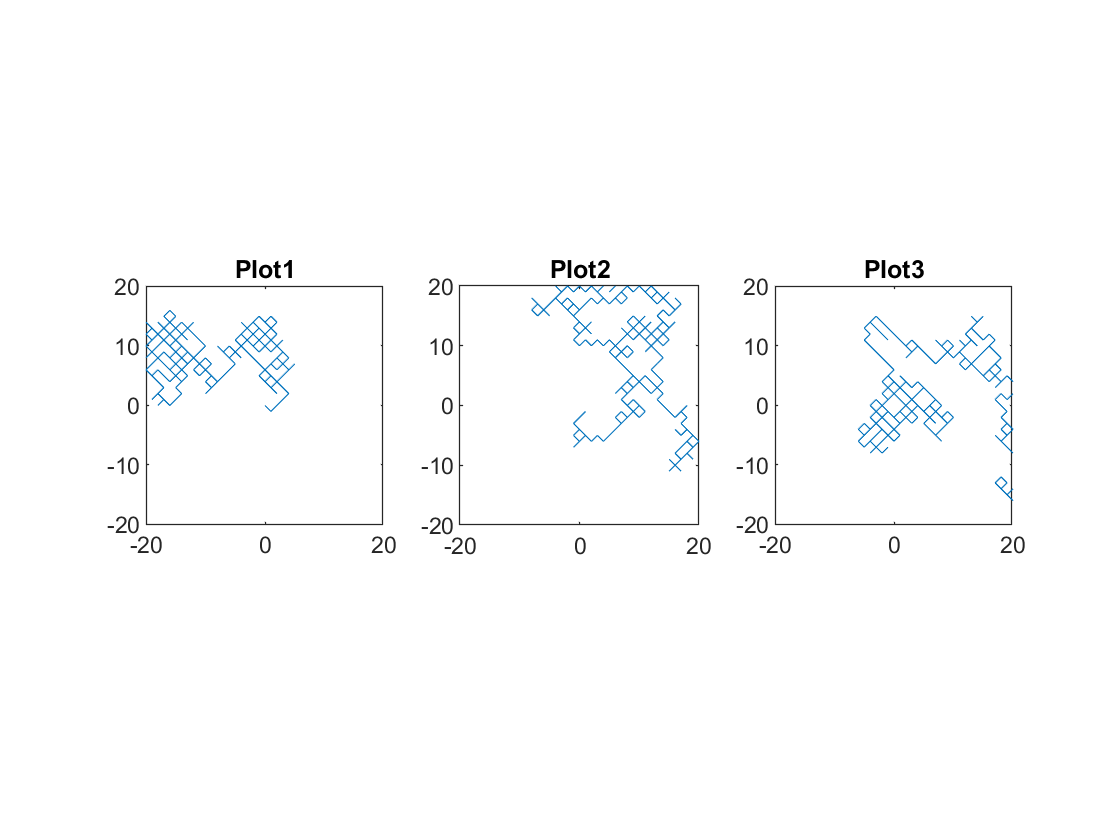

figure;
subplot(1,3,1)
plot(stepx, stepy)
axis equal
xlim([-20 20])
ylim([-20 20])
title('Plot1')

subplot(1,3,2)
plot(stepx2, stepy2)
axis equal
xlim([-20 20])
ylim([-20 20])
title('Plot2')

subplot(1,3,3)
plot(stepx3, stepy3)
axis equal
xlim([-20 20])
ylim([-20 20])
title('Plot3')